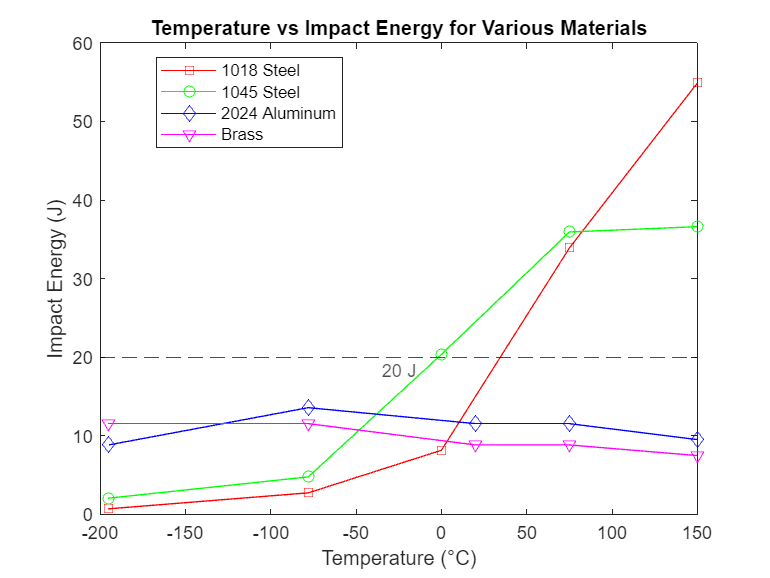

% This algorithm plots Temperature and Impact Energy for various materials found
% by the conducting of Charpy Impact Energy tests
% ATTRIBUTION: algorithm was completely written by myself, with the help of
% ChatGPT only to determine how to filter out NaN data values,
% Mathworks.com for MATLAB syntax

file = '/Users/vinay/Downloads/CharpympactEnergy_S6.csv';
data = readtable(file,'HeaderLines',3);

temp = data{:, 2};
steel_1018_ftlb = data{:,4};
steel_1045_ftlb = data{:,5};
al_2024_ftlb = data{:,6};
brass_ftlb = data{:,7};

% Convert impact energy from ftlb to J
steel_1018 = steel_1018_ftlb.*1.35582;
steel_1045 = steel_1045_ftlb.*1.35582;
al_2024 = al_2024_ftlb.*1.35582;
brass = brass_ftlb.*1.35582;

% Need to filter out NaN values to make sure plot is continuous
not_nan = ~isnan(steel_1018); % Logical index of non-NaN values
steel_1018_plot = plot(temp(not_nan), steel_1018(not_nan), '-s', 'Color', 'red');
hold on

% Repeat for other materials
not_nan = ~isnan(steel_1045);
steel_1045_plot = plot(temp(not_nan), steel_1045(not_nan), '-o', 'Color', 'green');

not_nan = ~isnan(al_2024);
al_2024_plot = plot(temp(not_nan), al_2024(not_nan), '-d', 'Color', 'blue');

not_nan = ~isnan(brass);
brass_plot = plot(temp(not_nan), brass(not_nan), '-v', 'Color', 'magenta');

yline(20, '--k', '20 J', 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'center', 'FontSize', 10);

xlabel('Temperature (°C)');
ylabel('Impact Energy (J)');
title('Temperature vs Impact Energy for Various Materials');

legend('1018 Steel','1045 Steel','2024 Aluminum','Brass', 'Location', 'best');

hold off